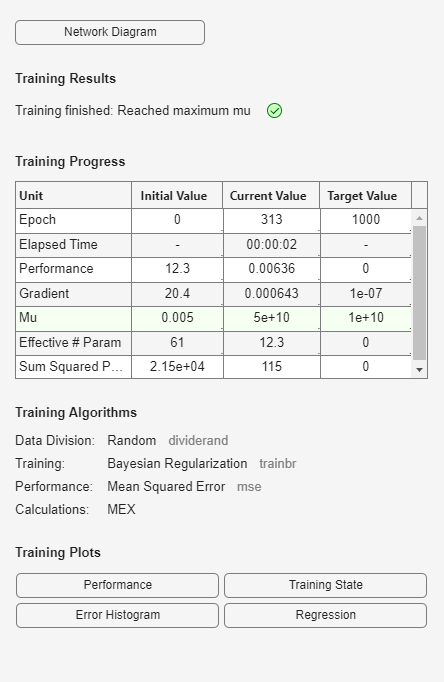

% 自动正则化 (trainbr)
% 该方法以自动方式确定最佳的正则化参数。此过程使用的一种方法是
% David MacKay 提出的贝叶斯框架 [MacK92]。
% 在此框架中，网络的权重和偏置假设为服从指定分布的随机变量。
% 正则化参数与这些分布的未知方差相关。然后，您可以使用统计方法来估计这些参数。
% 
% 贝叶斯正则化的详细讨论超出了本用户指南的范围。
% 有关结合使用贝叶斯正则化和 Levenberg-Marquardt 训练的详细说明，请参阅 [FoHa97]。
% 
% 贝叶斯正则化已通过函数 trainbr 实现。以下代码说明如何使用此函数来训练 1-20-1 网络，以逼近提高浅层神经网络泛化能力，避免过拟合的图中所示的含噪正弦波。（通过设置 net.divideFcn 取消数据划分，从而独立于早停法分析 trainbr 的效果。）

x = -1:0.05:1;
t = sin(2*pi*x) + 0.1*randn(size(x));
net = feedforwardnet(20,'trainbr');
net = train(net,x,t);

% 该算法的一个特点是，它可以度量网络实际上在使用多少个网络参数（权重和偏置）。
% 在本例中，最终经过训练的网络使用 1-20-1 网络中的 61 个总权重和偏置中的大约 12 个参数
% （由打印输出中的 #Par 指示）。不管网络中的参数个数变得多大，此实际参数个数应保持大致相同。
% （此论述假设网络已训练足够的迭代次数以确保收敛。）
% 
% trainbr 算法通常在网络输入和目标缩放到大致在 [−1,1] 范围内时效果最好。
% 此处的测试问题就是这种情况。如果您的输入和目标不在此范围内，
% 可以使用函数 mapminmax 或 mapstd 来执行缩放，如选择神经网络输入输出处理函数中所述。
% 默认情况下，使用 feedforwardnet 创建的网络包含 mapminmax 作为输入和输出处理函数。
% 
% 下图显示经过训练的网络的响应。与上一个图（图中 1-20-1 网络过拟合数据）相比，
% 您可以看到网络响应非常接近基础正弦函数（虚线），因此，网络对新输入具有很强的泛化能力。
% 您可以尝试更大的网络，但网络响应永远不会过拟合数据。这就消除了确定最优网络大小所需的猜测工作。
% 
% 当使用 trainbr 时，务必让算法运行到实际参数个数收敛为止。
% 训练可能会停止并显示“Maximum MU reached”消息，这是典型情形，
% 明确表示算法已真正收敛。如果误差平方和 (SSE) 和权重平方和 (SSW) 在几次迭代中相对恒定，
% 则也可以视为算法已收敛。出现这种情况时，您可能需要点击训练窗口中的 Stop Training 按钮。